S(2) = load('chirp');

sound(S(2).y,S(2).Fs);

gong = S(2).y;
Fs = S(2).Fs;

% load echo_file1_48000_normal.wav

% [y_caf,Fs] = audioread('echo_file1_48000_normal.caf');

% change sampling rate of mtlb
fs = 48000;
[P,Q] = rat(fs/Fs);

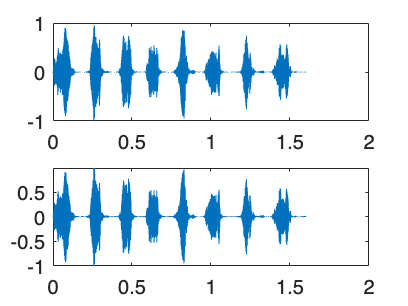

mtlb_new = resample(gong,P,Q);

subplot(2,1,1)
plot((0:length(gong)-1)/Fs,gong)
subplot(2,1,2)
plot((0:length(mtlb_new)-1)/(P/Q*Fs),mtlb_new)

% alpha: y(n)=x(n)+alpha*x(n−delta)
timelag = 0.23;
delta = round(fs*timelag);
alpha = 0.5;

orig = [mtlb_new;zeros(delta,1)];
echo = [zeros(delta,1);mtlb_new]*alpha;

mtEcho = orig + echo;

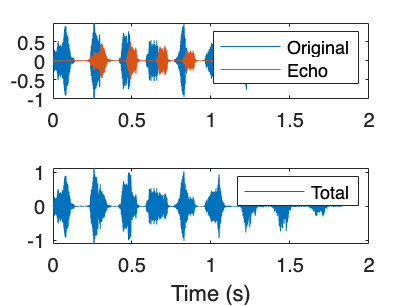

t = (0:length(mtEcho)-1)/fs;

subplot(2,1,1)
plot(t,[orig echo])
legend('Original','Echo')

subplot(2,1,2)
plot(t,mtEcho)
legend('Total')
xlabel('Time (s)')

% uncomment to hear echo
soundsc(mtEcho,fs)

% generate wav file of echo


fileName = "echo_file_chirp_48000_normal"

fileName = "echo_file_chirp_48000_normal"



mtEcho_normalized = mtEcho/(max(abs(mtEcho)));
%audiowrite(filename, mtEcho_normalized, fs)

audiowrite(char(fileName + ".wav"), mtEcho_normalized, fs)

if ismac
    cmd = "afconvert -f caff -d LEI16@" + num2str(fs) + " -c 1 " + fileName + ".wav " + fileName + ".caf"
end

cmd = "afconvert -f caff -d LEI16@48000 -c 1 echo_file_chirp_48000_normal.wav echo_file_chirp_48000_normal.caf"


system(cmd)

ans = 0

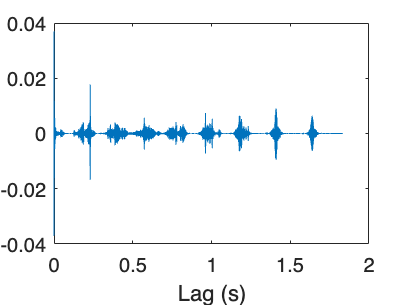

[Rmm,lags] = xcorr(mtEcho,'unbiased');

Rmm = Rmm(lags>0);
lags = lags(lags>0);

figure
plot(lags/fs,Rmm)
xlabel('Lag (s)')

[~,dl] = findpeaks(Rmm,lags,'MinPeakHeight',0.015);

a = [1 zeros(1,dl(2)-1) alpha];

mtNew = filter(1,a,mtEcho);

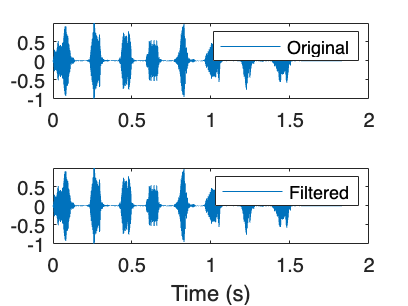

subplot(2,1,1)
plot(t,orig)
legend('Original')

subplot(2,1,2)
plot(t,mtNew)
legend('Filtered')
xlabel('Time (s)')

% To hear new w/o echo, uncomments
soundsc(mtNew,fs)
%quantizefir(a, 15)